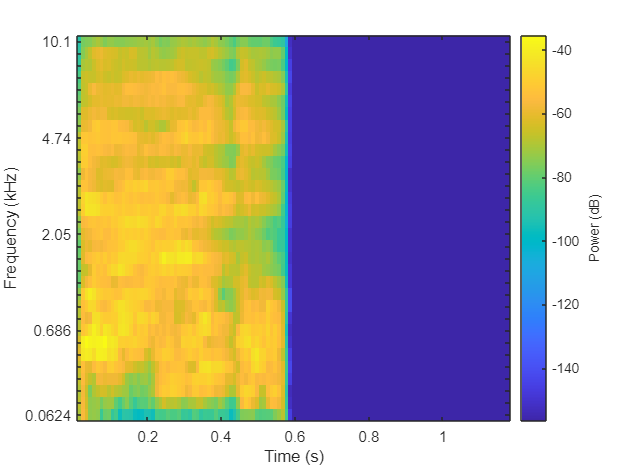

ads = audioDatastore('D:/all',IncludeSubfolders=true);
% Write my images here
outputLocation = fullfile(tempdir,"mySpectrograms");
% Create PNGs for all audio files.
writeall(ads,outputLocation,WriteFcn=@myCustomWriter);

function myCustomWriter(audioIn,writeInfo,~)
% Get the sample rate of the audio file
fs = 22050;
% Extract Mel spectrogram. This generates a plot.
melSpectrogram(audioIn,fs);
% Form image name
imagename = strrep(writeInfo.SuggestedOutputName,".wav",".png");
% Save the figure as an image
saveas(gcf,imagename);
end